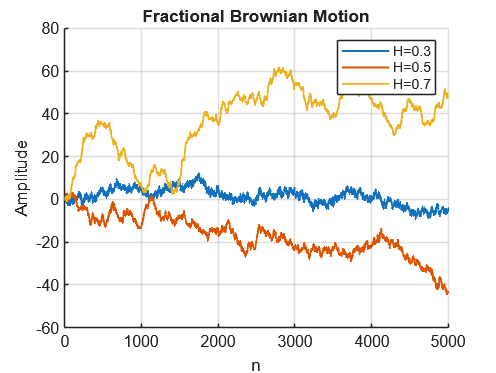

clear; close all; clc;

% Parameters
N = 5000;
Hvals = [0.3, 0.5, 0.7];
colors = lines(3);

% Preallocate
fbm = cell(1,3);
dh = cell(1,3);
h = cell(1,3);
cp = cell(1,3);
tauq = cell(1,3);
leaders = cell(1,3);
struct = cell(1,3);
% Generate fBm and compute wavelet leader stats
for i = 1:3
    fbm{i} = wfbm(Hvals(i), N);
    [dh{i}, h{i}, cp{i}, tauq{i}, leaders{i}, struct{i}] = dwtleader(fbm{i});
    
end

%% ---------------------------------------------------------
% 1. Plot the fBm signals
% ---------------------------------------------------------
x = 1:N;
figure;
hold on;
for i = 1:3
    plot(x, fbm{i}, 'LineWidth', 1.2, 'Color', colors(i,:));
end
legend("H=0.3","H=0.5","H=0.7", Location="NorthEast")
title("Fractional Brownian Motion")
xlabel("n"); ylabel("Amplitude"); grid on

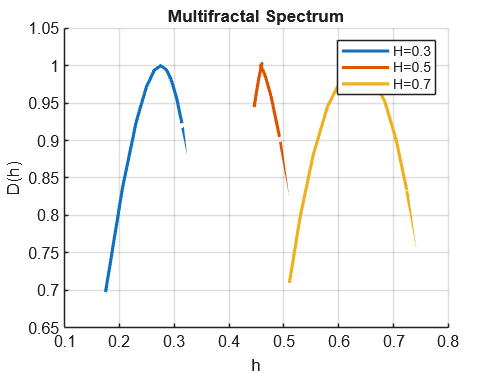


%% ---------------------------------------------------------
% 2. Multifractal Spectrum D(h)
% ---------------------------------------------------------
figure; hold on;
for i = 1:3
    plot(h{i}, dh{i}, 'LineWidth', 2, 'Color', colors(i,:));
end
xlabel("h"); ylabel("D(h)")
title("Multifractal Spectrum")
legend("H=0.3","H=0.5","H=0.7", Location="NorthEast")
grid on

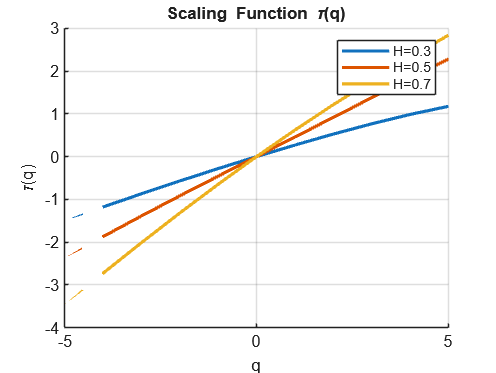


%% ---------------------------------------------------------
% 3. Scaling Function τ(q)
% ---------------------------------------------------------
q = -5:5;
figure; hold on;
for i = 1:3
    plot(q, tauq{i}, 'LineWidth', 2, 'Color', colors(i,:));
end
xlabel("q"); ylabel("\tau(q)")
title("Scaling Function \tau(q)")
legend("H=0.3","H=0.5","H=0.7", Location="NorthEast")
grid on

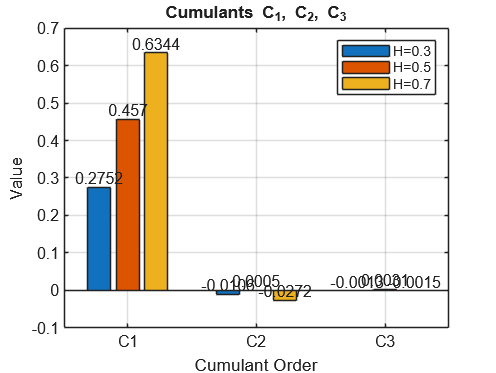


% C is a 3×3 matrix: rows = H values, columns = C1,C2,C3
C = cell2mat(cp');   % convert cumulant cell array to matrix

figure;
b = bar(C');   % grouped bar chart (C' makes groups = C1,C2,C3)
set(gca, 'XTickLabel', {'C1','C2','C3'})
xlabel("Cumulant Order")
ylabel("Value")
legend("H=0.3","H=0.5","H=0.7", Location="NorthEast")
title("Cumulants C_1, C_2, C_3")
grid on

% ---- Add value labels above each bar ----
xt = b(1).XEndPoints;  % x positions for first group
for k = 1:numel(b)
    x = b(k).XEndPoints;
    y = b(k).YEndPoints;
    labels = string(round(b(k).YData, 4));  % format values
    text(x, y, labels, ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment','bottom', ...
        'FontSize', 10)
end

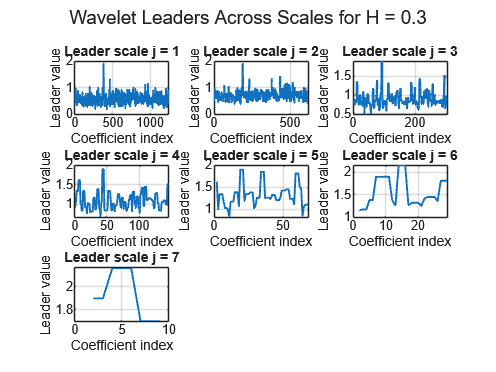

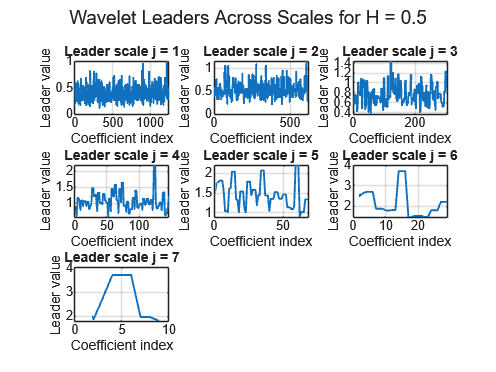

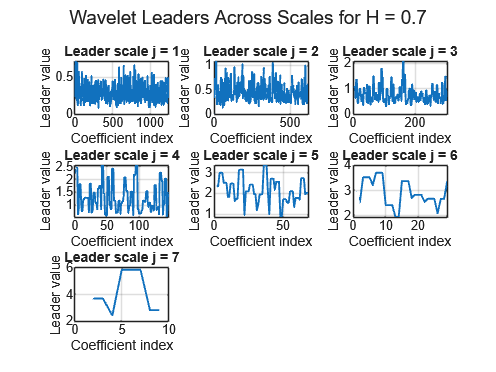

Hvals = [0.3, 0.5, 0.7]; % assuming leaders{1}, leaders{2}, leaders{3}
for i = 1:3
    numL = numel(leaders{i});
    rows = ceil(numL/3);

    figure;
    for j = 1:numL
        subplot(rows, 3, j)
        plot(leaders{i}{j}, 'LineWidth', 1.2)
        title("Leader scale j = " + string(j))
        xlabel("Coefficient index")
        ylabel("Leader value")
        grid on
    end

    sgtitle("Wavelet Leaders Across Scales for H = " + string(Hvals(i)))
end

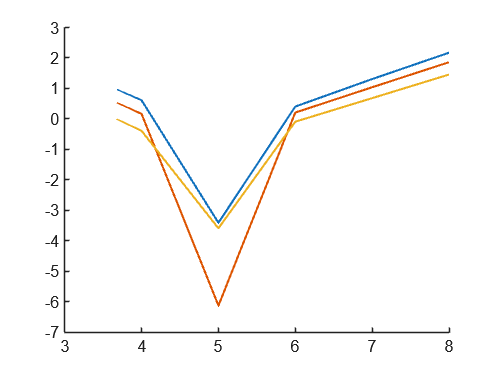

Index in position 1 exceeds array bounds. Index must not exceed 3.


%% ---------------------------------------------------------
% 6. Structure Functions S(q,a) (log–log scaling plot)
% ---------------------------------------------------------
qvals = -5:5;

for i = 1:3
    S = struct{i}.Tq(:, 1:11);      % structure functions
    loga = struct{i}.logscales;     % log2(a)

    figure; hold on;
    for qi = 1:numel(qvals)
        plot(loga, log2(S(:,qi)), 'LineWidth', 1.3, 'Color', colors(qi,:));
    end

    xlabel("log_2(scale a)")
    ylabel("log_2(S(q,a))")
    title("Structure Functions S(q,a) for H = " + string(Hvals(i)))
    legend("q="+string(qvals), Location="NorthWest")
    grid on
end